## **Connect and Sample Data from a Hokuyo URG-40LX Laser Scanner.mlx**

*Code to read and analyze data from a ***Hokuyo URG-40LX Laser Scanner. ***Displays a labeled plot of circular targets,*

*and a continous print out of the angle range of holes within the plane of view.*

*Before running, please run UrgBenriPlusV2.2.0 to ensure proper connection has been made to the lidar.*

*Bennett and Tigey: 3/22/22*

disp("Program running...");  %Indicate lidar code starts okay

Program running...


%To avoid incesent error messages in Windows 10, we will temportarily
%disable error warnings

%Lidar is contained in a Matlab serial object, we need to clean up any old
%lidar objects in the workspace to prevent conflicts when we create a new
%one. For Fun-Robo, don't worry about what an object is for now, just
%treat it like a big fancy function.
serialObjs = instrfind;      %Read instrument objects from memory to MATLAB workspace
if ~isempty(serialObjs)      %If there are old objects, close them
    fclose(serialObjs);      %close serial port attatched to old Lidar
    delete(serialObjs);      %delete old lidar objects
end

clc                          %clear command window
clear                        %clear MATLAB workspace

## **Specify which serial port (USB) you have the test bench Hokuyo Lidar plugged into**

%identify and connect to comport
comPort = serialportlist("available");
disp("comPort Identified:")

comPort Identified:


comPort

comPort = 1×2 string array
    "COM4"    "COM12"


## **Connect to Hokuyo Lidar and set its serial communication parameters**

s = serial('port') creates a serial port object s associated with the serial port specified by 'port'. If 'port' does not exist, or if it is in use, you cannot connect the serial port object to the device. 

disp("Conneting to lidar and setting Lidar parameters.");

Conneting to lidar and setting Lidar parameters.


disp("Expect a short delay while setting...")

Expect a short delay while setting...


lidar = serial("COM12",'BaudRate', 115200);  %create a serial port for Lidar
set(lidar,'Timeout',2);                     %set communication link timeout
set(lidar,'InputBufferSize',20000);         %set data input buffer size
set(lidar,'Terminator','LF/CR');            %set data stream terminator for fprintf
                                            %and fscanf. A read operation
                                            %with fgetl, fgets, or fscanf
                                            %completes when the terminator
                                            %value is read
%write a set of Hokuyo parameters to Lidar to configure it
fopen(lidar);                   %connects the serial port object, the lidar
pause(0.3);                     %pauses to allow command to transmit
fprintf(lidar,'SCIP2.0');       %writes string cmd to the lidar
pause(0.3);                     %pause to allow cmd to the lidar
fscanf(lidar);                  %reads ASCII data from the device connected to lidar
fprintf(lidar,'VV');            %pause to allow data to be read
pause(0.3);
fscanf(lidar,'BM');
pause(0.3);
fscanf(lidar);
fprintf(lidar,'MD0044072500');  %dont worry about what commands are sent for now
pause(0.3);
fscanf(lidar);
clc
disp("Lidar Set");

Lidar Set


## Initialize Lidar display

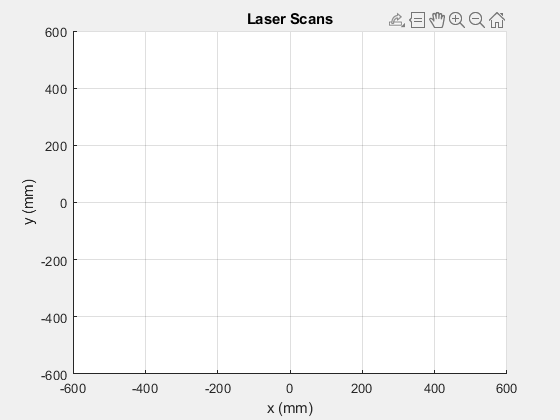

% stand alone figire window

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

laserRange = line('Parent', LaserPlot1.axis1, 'XData', [], 'YData', [], 'LineStyle', 'none', ...
    'marker', '.', 'color', 'b', 'LineWidth', 2);
grid on
axis([-600 600 -600 600])
xlabel('x (mm)')
ylabel('y (mm)')

## **Sample and Visualize Data**

read Lidar over USB, parse data, create plot of data in 60 sec max loop

**Dont pause and leave this code, needs to complete and then clean shutdown to avoid jamming com link to Lidar**

disp("Read and Plot Lidar Data, type and hold ctrl-c to stop")

Read and Plot Lidar Data, type and hold ctrl-c to stop



angles = (-120:240/682:120-240/682) * pi / 180; % Convert sensor steps to angles
tStart = tic;                                   %Start timer
iscan = 0;

while (iscan == 0)                              % countinuous loop

    [A] = FunRoboLidarScan(lidar);              % actual scan data
    data = filter(angles, A, 600);              %filtered scan data
    data2 = polCart(data);                      %convert to cartesian coords
    
    findObjects(data2');                        %identify objects in the points

    readout(A, angles, 600, 3);                 %print holes 3 degrees across at 600mm

    pause(0.2)                                  % allow serial to keep up
    
    tElapsed = toc(tStart);                     % measure time since experiment start
    if (tElapsed > 60)                          % if gone too long, stop loop
        iscan = 1;
    end

end

## Disconnect Lidar

Please always run this section so the lidar doesnt become sentient 

%disconnect lidar
fprintf(lidar, 'QT');
fclose(lidar);
clear lidar;
warning('on');
disp("The lidar has successfully been terminated.")

## Functions

function [filtered] = filter(angles, A, cutoffDist)
    %Filters data to exclude points outside of cut off distance 
    %Takes A in mm, angles in rad, cut off distance in mm
    %Returns filtered data matrix
    
    A(A > cutoffDist) = 0;
    A(A < 40) = 0;
    
    filtered = [angles; A];
end

function data = polCart(polData)
    %converts data to cartesian coordinates
    %takes polar data, returns cartesian coordinate matrix

    X = polData(2, :).*cos(polData(1, :));          % Trig to find x-coord
    Y = polData(2, :).*sin(polData(1, :));          % Trig to find y-coord 
    data = [X; Y];
            
end

function [rangescan]=FunRoboLidarScan(lidar)
%Get a LIDAR Scan
%Returns a range vector of 682 elements after a Lidar Scan from min step
% to max step. Range Values correspond from -120 to +120 degrees.
% Author- Shikhar Shrestha, IIT Bhubaneswar
% Lightly modified by Olin Studnet 2019

proceed=0;
fprintf(lidar,'GD0044072500');

while (proceed==0)
    if lidar.BytesAvailable >= 2134
        data = fscanf(lidar,'%c',2134);
        proceed = 1;
    end
end

i = find(data == data(13));
rangedata=data(i(3)+1:end-1);

for j=0:31
    onlyrangedata((64*j)+1:(64*j)+64)=rangedata(1+(66*j):64+(66*j));
end

j=0;

for i=1:floor(numel(onlyrangedata)/3)
    encodeddist(i,:)=[onlyrangedata((3*j)+1) onlyrangedata((3*j)+2) onlyrangedata((3*j)+3)];
    j=j+1;
end

for k=1:size(encodeddist,1)
    rangescan(k)=decodeSCIP(encodeddist(k,:));
end

end

function rangeval=decodeSCIP(rangeenc)
% Function to decode range information transmitted using SCIP2.0 protocol.
% Works for only two and three bit encoding.
% Author- Shikhar Shrestha, IIT Bhubaneswar

% Check for 2 or 3 Character Encoding
if rangeenc(1)=='0' && rangeenc(2)=='0' && rangeenc(3)=='0'
    rangeval=0;
    return;
end
if rangeenc(1)=='0'
    dig1=((rangeenc(2)-'!')+33);
    dig2=((rangeenc(3)-'!')+33);
    dig1sub=dig1-48;
    dig2sub=dig2-48;
    dig1bin=dec2bin(dig1sub,6);
    dig2bin=dec2bin(dig2sub,6);
    rangeval=bin2dec([dig1bin dig2bin]);
    return;
else
    dig1=((rangeenc(1)-'!')+33);
    dig2=((rangeenc(2)-'!')+33);
    dig3=((rangeenc(3)-'!')+33);
    dig1sub=dig1-48;
    dig2sub=dig2-48;
    dig3sub=dig3-48;
    dig1bin=dec2bin(dig1sub,6);
    dig2bin=dec2bin(dig2sub,6);
    dig3bin=dec2bin(dig3sub,6);
    rangeval=bin2dec([dig1bin dig2bin dig3bin]);
    return;
    
end
    
end

function [xo, yo, R] = circle_fit(x,y)
% Identifies circles within sets of points
% Takes x coordinates and y coordinates
% Outputs circle x coordinate center, circle y coordinate\
% center, and circle radius
x = x(:);
y = y(:);

% Fit a circle to the data through least squares calc
A = [-2*x -2*y ones(length(x),1)];
x = A\-(x.^2+y.^2);

%pull x coord, y coord, and calc r
xo=x(1);
yo=x(2);
R = sqrt(  xo.^2 + yo.^2  - x(3));

end

function [objects, circles] = findObjects(X)
    % run DBSCAN algorithm for object recognition
    idx = dbscan(X, 20, 5);
    
    %Label each point with what cluster it belongs to
    objects = [X(:,1), X(:,2), idx];

    %initialixze circles matrix
    circles = [];

    %cycle through each object
    for i = 1:max(idx)
        %select one group of points by idx value
        object = objects(objects(:, 3) == i, :);  
        %calculate linear fit of points in the object
        mdl = fitlm(object(:,1), object(:,2));
        %calculate circle fir of points in the object
        [xc, yc, r] = circle_fit(object(:,1), object(:,2));
        %if sufficiently circular, recognize it as a circle
        if(r < 130 && r > 10 && mdl.Rsquared.Ordinary < 0.6)
            %assign circle's values to circle matrix
            circles = [circles; xc yc r];
        end
    end

    hold on
    clf
    %plot x coor, y coord, and object identity
    gscatter(objects(:,1), objects(:, 2), objects(:,3))

    %plot -600 to 600 mm for x and y
    range = 600;
    axis([-range, range, -range, range])

    %plot each circle, and label with x and y coord of centeroid
    for i = 1:size(circles,1)
        viscircles([circles(i, 1) circles(i,2)], circles(i,3));
        text(circles(i, 1), circles(i,2), strcat(num2str(int16(circles(i,1))), ...
            ", ", num2str(int16(circles(i,2)))));
        X = circles(i, 1);
        Y = circles(i, 2);
        ang = atand(X/Y);
        targetRange = ['Target Detected: Bearing of ', num2str(ang), ' degrees.'];
        disp(targetRange);
        fprintf('\n');        %new line
    end
    hold off
        
end

function readout(A, angles, cutOffDist, cutOffAng)
%display position and bearing of holes identified by the lidar.
%Takes position data, angle array, cut off distance, and cut off
%angle as inputs, and displays range of angles that are "open" 
%for the robot
%Bennett Taylor Rev 1

    %initialize holeVals matrix, same length as measures positons
    holeVals = zeros(1,size(A,2));

    %for each position
    for i = 1:size(A,2)
        
        %if the distance is above the cut off, store its angle
        if A(1,i) >= 0 && A(1,i) >= cutOffDist
            holeVals(1,i) = angles(1,i);

        % when a non-hole value is found
        elseif A(1,i) >= 0 && A(1,i) < cutOffDist
            holeVals(holeVals == 0) = [];       %purge unused columns
            Maxim = max(holeVals,[],'all');     %ident max angle
            maximDeg = rad2deg(Maxim);          %convert to degrees
            Minim = min(holeVals,[],'all');     %ident min angle
            minimDeg = rad2deg(Minim);          %convert to degrees
            holeRange = ['Hole Detected: ', num2str(minimDeg), ' degrees to ', num2str(maximDeg),' degrees.'];
            if (abs(maximDeg-minimDeg) >= cutOffAng) %if the hole is big enough
              disp(holeRange);      %display the hole range
              fprintf('\n');        %new line
            end

            holeVals = zeros(1,size(A,2)); %reset holeVals matrix
        end
        
    end
    
    fprintf('\n');           %new line for the next iteration
end       